# Datasets y visualización

## Importar con readtable y readmatrix

% readmatrix
area_mm=readmatrix("../../Digitalizacion de señales/S3/Utils4SP/Datasets/areaMM.txt",'Delimiter','   ');

% readtable
PSD_bands=readtable("../../Digitalizacion de señales/S3/Utils4SP/Datasets/2021.10.04_IntensidadBobinas.xlsx");

## Función custom de Import File

%Pasa sonda Cassini
Cassini=importfile_cassini("../../Digitalizacion de señales/S3/Utils4SP/Datasets/05358_mrdcd_sdfgmc_krtp_1s.asc")

Cassini = 86136×8 table
           FechaHora             Bx_nT     By_nt     Bz_nt     Bmag_nt       X_km           Y_km         Z_km  
    ________________________    _______    ______    ______    _______    ___________    ___________    _______

    2005 000 24 00 00 01 500    -2.7452    5.0172    1.3641    5.8797     -4.6408e+05    -5.8423e+05    -5057.4
    2005 000 24 00 00 02 500     -2.744    5.0013    1.3821    5.8698     -4.6416e+05    -5.8416e+05    -5057.4
    2005 000 24 00 00 03 500    -2.7611    4.9922     1.362    5.8654     -4.6424e+05    -5.8408e+05    -5057.4
    2005 000 24 00 00 04 500    -2.7872    4.9906    1.3063    5.8637     -4.6433e+05      -5.84e+05    -5057.3
    2005 000 24 00 00 05 500   

## Importar audio

[buho,fs_buho]=audioread("../../Digitalizacion de señales/S3/Utils4SP/Datasets/Owl.wav");
% Escuchar
sound(buho,fs_buho)


## Datastore

% % Le indicamos que una carpeta es un datastore
% ds=datastore("../../Digitalizacion de señales/S3/Utils4SP/Datasets/atmosfera_partLogger_V2/")
% ds.VariableNames=["Fecha" "Hora" "Pres_kpa" "Temp_C" "Hum_perc" "Bat_V"]
% ds.TextscanFormats=["%s" "%s" "%f" "%f" "%f" "%f"];
% %leer todas las entradas
% atmosfera=readall(ds);
% 
% %Parche por si la tabla ya se importo
% %atmosfera.Properties.VariableNames=["Fecha" "Hora" "Pres_kpa" "Temp_C" "Hum_perc" "Bat_V"]


## Primeras lecturas atmosféricas

ds=datastore("../../Digitalizacion de señales/S3/Utils4SP/Datasets/AtmosferaLogger/");
ds.VariableNames=["Fecha" "Hora" "Pres_kpa" "Temp_C" "Hum_perc"]

ds =   TabularTextDatastore with properties:

                      Files: {
                             ' .../S3/Utils4SP/Datasets/AtmosferaLogger/210425.txt';
                             ' .../S3/Utils4SP/Datasets/AtmosferaLogger/210426.TXT';
                             ' .../S3/Utils4SP/Datasets/AtmosferaLogger/210427.TXT'
                              ... and 35 more
                             }
                    Folders: {
                             ' .../paush/Digitalizacion de señales/S3/Utils4SP/Datasets/AtmosferaLogger'
                             }
               FileEncoding: 'UTF-8'
   AlternateFileSystemRoots: {}
         VariableNamingRule: 'modify'
          ReadVariableNames: false
              VariableNames: {'Fecha', 'Hora', 'Pres_kpa' ... and 2 more}
             DatetimeLocale: en_US

  Text Format Properties:
             NumHeaderLines: 0
                  D

ds.TextscanFormats=["%s" "%s" "%f" "%f" "%f"]

ds =   TabularTextDatastore with properties:

                      Files: {
                             ' .../S3/Utils4SP/Datasets/AtmosferaLogger/210425.txt';
                             ' .../S3/Utils4SP/Datasets/AtmosferaLogger/210426.TXT';
                             ' .../S3/Utils4SP/Datasets/AtmosferaLogger/210427.TXT'
                              ... and 35 more
                             }
                    Folders: {
                             ' .../paush/Digitalizacion de señales/S3/Utils4SP/Datasets/AtmosferaLogger'
                             }
               FileEncoding: 'UTF-8'
   AlternateFileSystemRoots: {}
         VariableNamingRule: 'modify'
          ReadVariableNames: false
              VariableNames: {'Fecha', 'Hora', 'Pres_kpa' ... and 2 more}
             DatetimeLocale: en_US

  Text Format Properties:
             NumHeaderLines: 0
                  D

atmosfera=readall(ds)

atmosfera = 546110×5 table
      Fecha           Hora        Pres_kpa    Temp_C    Hum_perc
    __________    ____________    ________    ______    ________

    {'210425'}    {'21:03:51'}     78.05      28.79      33.52  
    {'210425'}    {'21:03:56'}     78.05      29.12      33.12  
    {'210425'}    {'21:04:01'}     78.05      29.16      33.09  
    {'210425'}    {'21:04:06'}     78.05       29.2      36.58  
    {'210425'}    {'21:04:11'}     78.05       29.3      35.68  
    {'210425'}    {'21:04:16'}     78.05      29.37      34.48  
    {'210425'}    {'21:04:22'}     78.05      29.43      33.99  
    {'210425'}    {'21:04:27'}     78.05       29.5         34  
    {'210425'}    {'21:04:32'}     78.05      29.57      34.21  
    {'210425'}    {'21:04:37'}     78.05      29.63      33.81  
    {'210425'}    {'21

## Reordenando

%Sólo si importa fecha y hora en dos columnas
atmosfera.DateTime=string(atmosfera.Fecha)+" "+string(atmosfera.Hora);
%Pasar de texto a fecha-hora
atmosfera.DateTime=datetime(atmosfera.DateTime,'Format','yyyyMMdd HH:mm:ss');


## Limpieza

Tomaremos los datos entre el 18 de mayo y el 26 de mayo a las 6:00 am

%Puntos inicial y final en el tiempo
T1=datetime(2021,5,18,6,00,00) 

T1 = datetime
   18-May-2021 06:00:00


T2=datetime(2021,5,26,6,00,00)

T2 = datetime
   26-May-2021 06:00:00



index= atmosfera.DateTime>T1 &...
    atmosfera.DateTime<T2;

atmosfera_part=atmosfera(index,:);


## Limpieza de NAN's

sum(ismissing(atmosfera_part))

ans =      0     0     0    11    61     0


summary(atmosfera_part)

Variables:

    Fecha: 137522×1 cell array of character vectors

    Hora: 137522×1 cell array of character vectors

    Pres_kpa: 137522×1 double

        Values:

            Min        77.55  
            Median     78.06  
            Max        78.46  

    Temp_C: 137522×1 double

        Values:

            Min             13.38  
            Median          21.01  
            Max             100    
            NumMissing      11     

    Hum_perc: 137522×1 double

        Values:

            Min             15.27  
            Median          50.16  
            Max             99.97  
            NumMissing      61     

    DateTime: 137522×1 datetime

        Values:

            Min       20210518 06:00:03
            Median    20210522 05:59:48
            Max       20210526 05:59:55




%Remover filas con NaNs
atmosfera_noNaNs=rmmissing(atmosfera_part);
summary(atmosfera_noNaNs)

Variables:

    Fecha: 137450×1 cell array of character vectors

    Hora: 137450×1 cell array of character vectors

    Pres_kpa: 137450×1 double

        Values:

            Min        77.55  
            Median     78.06  
            Max        78.46  

    Temp_C: 137450×1 double

        Values:

            Min        13.38  
            Median     21.01  
            Max        46.86  

    Hum_perc: 137450×1 double

        Values:

            Min         15.27 
            Median     50.155 
            Max         99.97 

    DateTime: 137450×1 datetime

        Values:

            Min       20210518 06:00:03
            Median    20210522 05:57:17
            Max       20210526 05:59:55



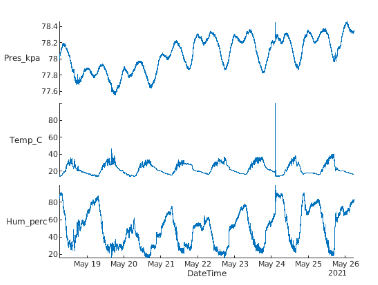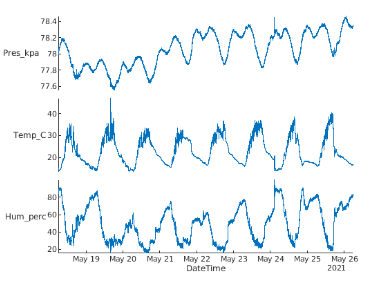

Con NaNs                                                                        Sin NaNs

## Ploteo exploratorio

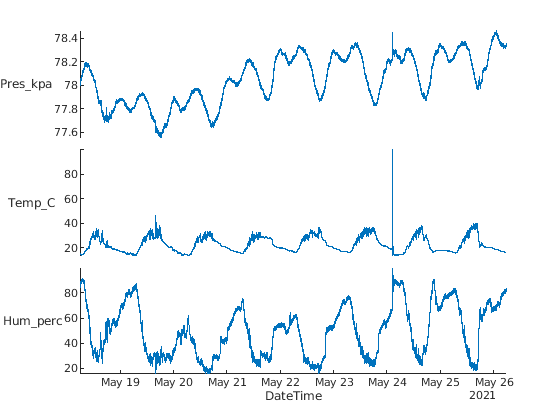

figure
stackedplot(atmosfera_part,'XVariable','DateTime')

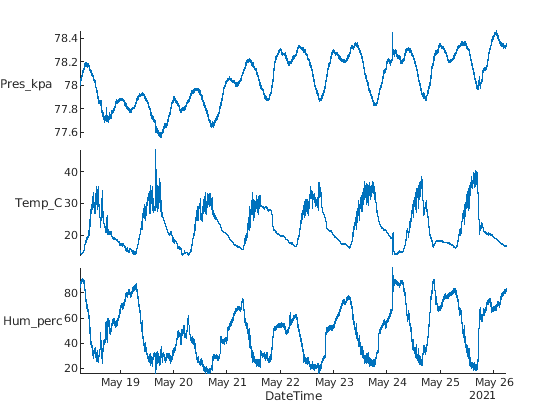


figure
stackedplot(atmosfera_noNaNs,'XVariable','DateTime')

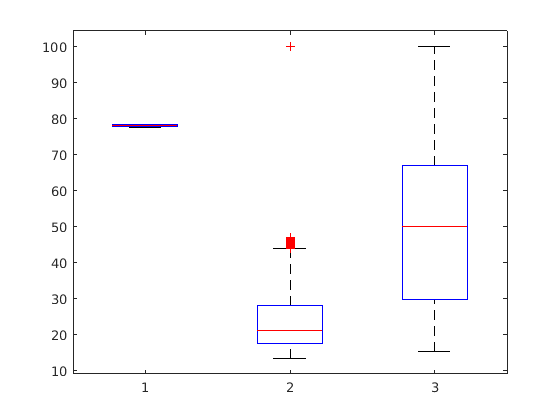


figure
boxplot(atmosfera_part{:,["Pres_kpa" "Temp_C" "Hum_perc"]})

## Histograma

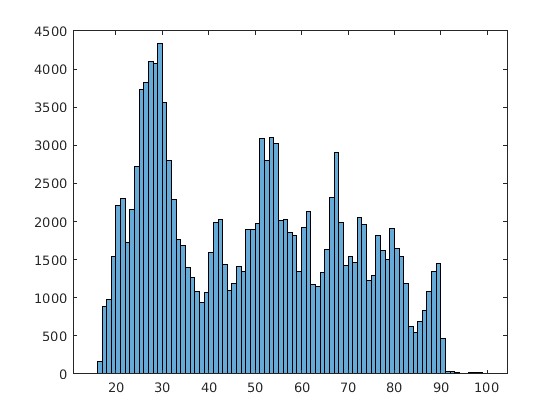

figure
histogram(atmosfera_part.Hum_perc)


figure
histogram(atmosfera_part.Hum_perc,'BinWidth',1)

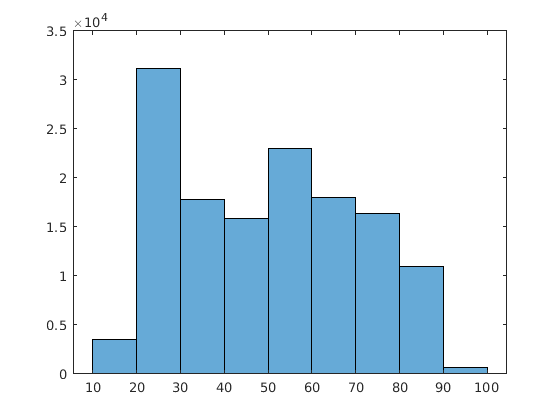


figure
histogram(atmosfera_part.Hum_perc,'BinWidth',10)

## Dispersión

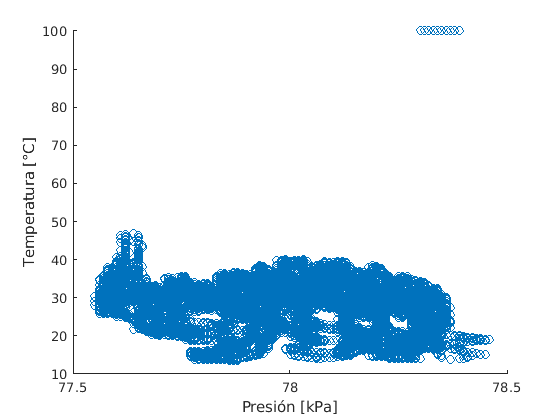

scatter(atmosfera_part.Pres_kpa,atmosfera_part.Temp_C)
xlabel("Presión [kPa]")
ylabel("Temperatura [°C]")

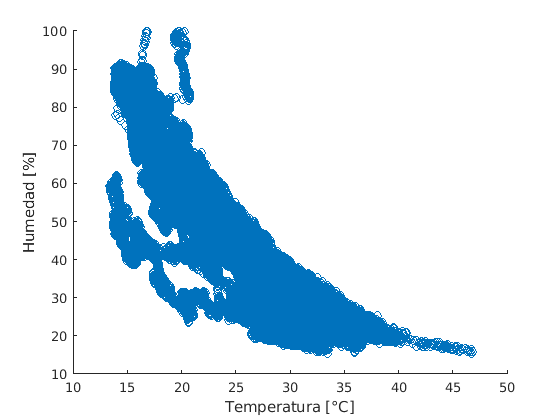


scatter(atmosfera_part.Temp_C,atmosfera_part.Hum_perc)
xlabel("Temperatura [°C]")
ylabel("Humedad [%]")

## Plot matrix

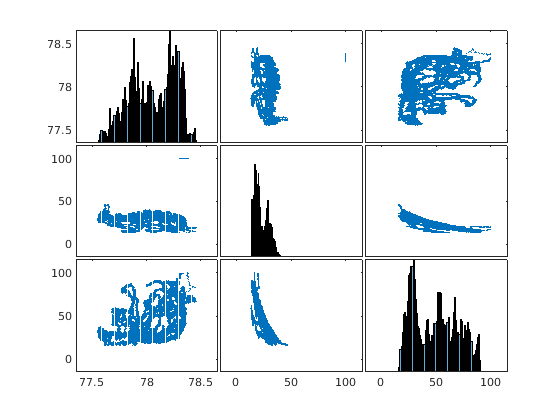

figure 
plotmatrix(atmosfera_part{:,["Pres_kpa" "Temp_C" "Hum_perc"]})

## Tiledlayout

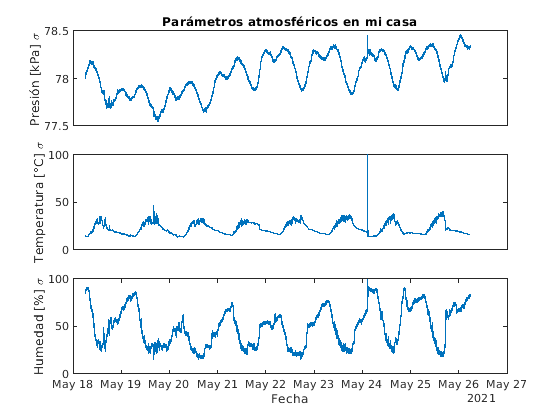

tiledlayout(3,1) %o flow
nexttile
plot(atmosfera_part.DateTime,atmosfera_part.Pres_kpa)
ylabel("Presión [kPa] \sigma")
title("Parámetros atmosféricos en mi casa")
set(gca,'xtick',[])

nexttile
plot(atmosfera_part.DateTime,atmosfera_part.Temp_C)
ylabel("Temperatura [°C] \sigma")
set(gca,'xtick',[])

nexttile
plot(atmosfera_part.DateTime,atmosfera_part.Hum_perc)
ylabel("Humedad [%] \sigma")
xlabel("Fecha")

## Agrupación y orden

% Darle categorías a temperatura
%Fronteras de las categorías
edges=[-30 15 20 55]

edges =    -30    15    20    55



% Categorías
categorias=["Frio" "Templado" "Caliente"]

categorias = 1×3 string array
    "Frio"    "Templado"    "Caliente"


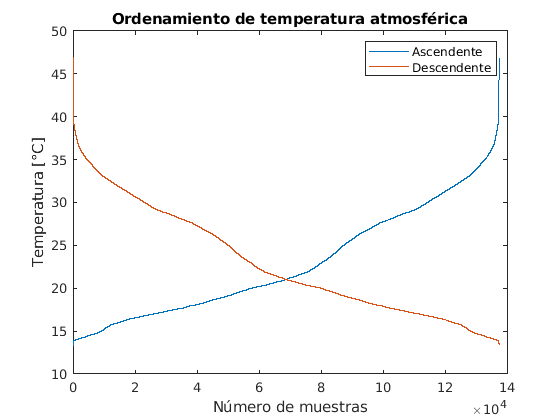


%Clasifico las temperaturas con un categórico
temp_cats=discretize(atmosfera_noNaNs.Temp_C,edges,'categorical',categorias);

%Agrego a la tabla original
atmosfera_noNaNs.temp_cats=temp_cats;

%Ordenamiento
temp_Descend=sort(atmosfera_noNaNs.Temp_C,'descend');
temp_Ascend=sort(atmosfera_noNaNs.Temp_C,'ascend');

figure
plot([temp_Ascend temp_Descend])
ylabel("Temperatura [°C]")
xlabel("Número de muestras")
legend("Ascendente", "Descendente")
title("Ordenamiento de temperatura atmosférica")

## G scatter y pareto chart

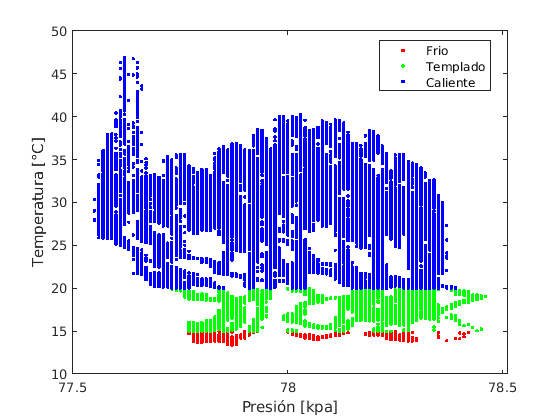

figure
gscatter(atmosfera_noNaNs.Pres_kpa,atmosfera_noNaNs.Temp_C,atmosfera_noNaNs.temp_cats)
xlabel("Presión [kpa]")
ylabel("Temperatura [°C]")

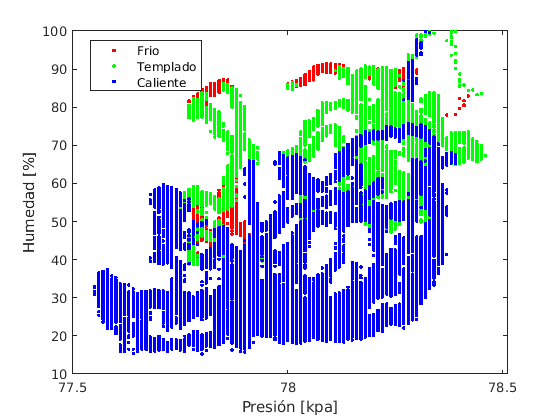


figure
gscatter(atmosfera_noNaNs.Pres_kpa,atmosfera_noNaNs.Hum_perc,atmosfera_noNaNs.temp_cats)
xlabel("Presión [kpa]")
ylabel("Humedad [%]")

## Pareto

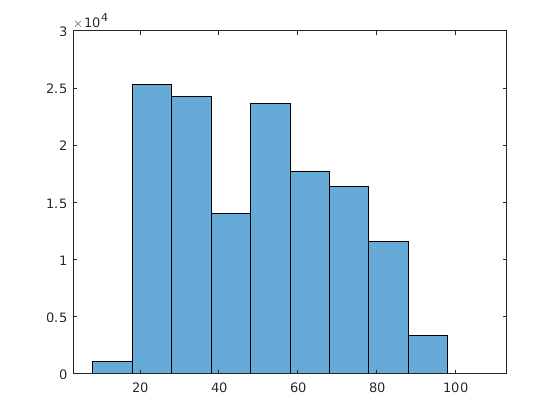

h=histogram(atmosfera_noNaNs.Hum_perc,10);

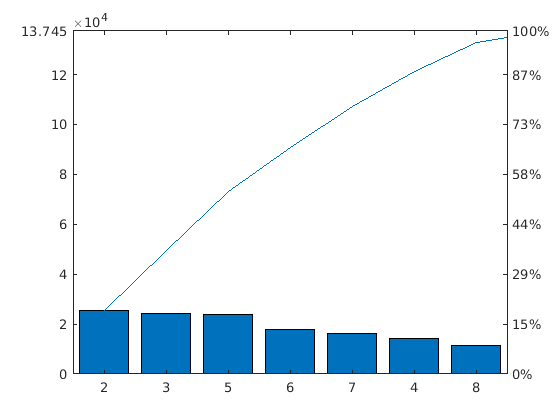

cuentas=h.BinCounts;


figure
pareto(cuentas)